a) Formulate QP problem.

sigma = [
    0.2 -0.2 -0.12 0.02;
    -0.2 1.4 0.02 0;
    -0.12 0.02 1 -0.4;
    0.02 0 -0.4 0.2
    ];

expectation = [1.1 1.35 1.25 1.05]';

Aeq = ones(4,1)';
beq = 1;

A = [-expectation'; -eye(4)];

f = zeros(1,4);

figure
data = zeros(35,1)

data =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


count = 2

count = 2

x = zeros(35,1)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for rmin = 1:0.01:1.35
    bneq = [-rmin, zeros(1,4)]';
    p = quadprog(sigma, f, A, bneq, Aeq, beq);
    risk = p'*sigma*p;
    exp_return = p'*expectation;
    data(count) = risk;
    x(count) = exp_return;
    count = count + 1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

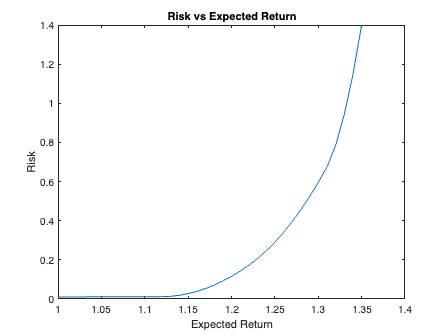


plot(x, data);
title('Risk vs Expected Return')
xlabel('Expected Return');
ylabel('Risk')
xlim([1,1.4])

Risk increases approximately linearly with return.

b) Plot portfolio allocation


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


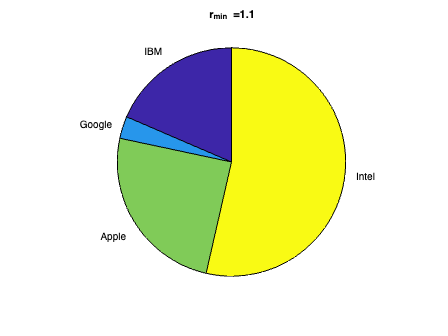


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


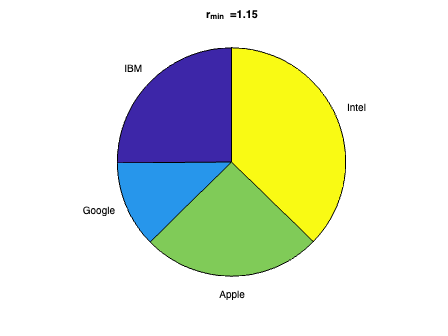


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


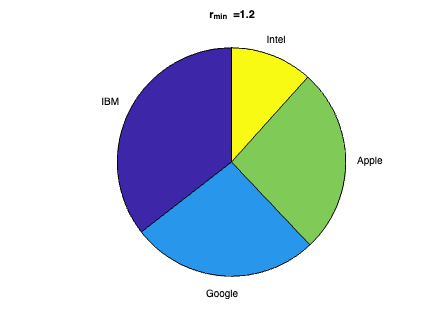


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


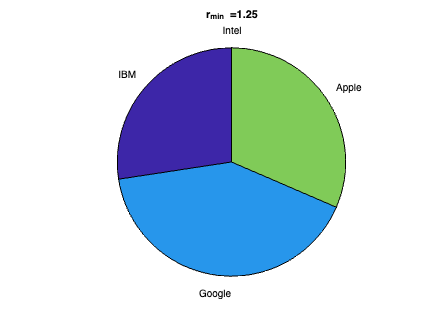


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


labels = {'IBM', 'Google', 'Apple', 'Intel'};
for rmin = 1.1:0.05:1.3
    figure
    bneq = [-rmin, zeros(1,4)]';
    p = quadprog(sigma, f, A, bneq, Aeq, beq);
    pie(p, labels);
    title(strcat('r_{min} = ', num2str(rmin)));
end

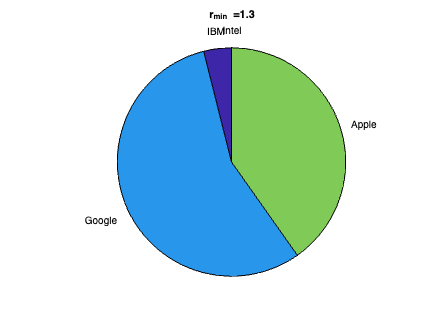


xlabel('Expected Return');
ylabel('Risk')

For low r_min, we invest heavily in Intel to minimize risk.

For higher r_min, we require more risky investments in Google and Apple. Allocation for Intel decreases as a result.